# 创建一个3DGDYTB模型并提取费米面附近轨道

## 生成GDY3D_TB

GDY3D= HR(18);
GDY3D= GDY3D<'POSCAR_GDY';
GDY3D= GDY3D<'KPOINTS_GDY';
GDY3D.orbL
GDY3D.quantumL

- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 1];
Accuracy = 3;
r_max_search = 3.5;
d_max = 3.5       ;
GDY3D= GDY3D.nn_sk_smart(search_range,Accuracy ,r_max_search);

- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = HR.nn_information(GDY3D)

- 这里我们取 hopping

recommend_label_cut = sum(Rnn<d_max);
level_cut = 12;
GDY3D= GDY3D.H_TB_gen_SK(level_cut,[1 1 1],-1); % -1 for chiral mode;

- 查看一下体系的未知量（symbolic）

- GDY3D.symvar_list

## 参数

VppP_1 = 3.34;
VppP_2 = 2.99;
VppP_3 = 2.82;
VppP_4 = 2.71*0.6;

VppP_5 = 0.0;
VppP_6 = 0;
VppP_7 = 0;
VppP_8 = 0;
VppP_9 = 0;
VppP_11 = 0;

VppP_10 = 0.0;
VppP_12 = 0.0;


VppS_1 = 0;
VppS_2 = 0;
VppS_3 = 0;
VppS_4 = 0;
VppS_5 = 0;
VppS_6 = 0;
VppS_7 = 0;
VppS_8 = 0;
VppS_9 = 0;
VppS_10 = 0;
%% for good example we set VppS_11 to zero
%ppS_11 = 0.463;% u2
VppS_11 = 0.463;% u2
VppS_12 = 0.42;% u1

## 能带

GDY3D_n = Subsall(GDY3D);
GDY3D_n= GDY3D_n<'KPOINTS_GDY';
% bulk band
EIGENCAR =GDY3D_n.EIGENCAR_gen();
% plot
[klist_l,kpoints_l,kpoints_name] = GDY3D_n.kpath_information();
bandplot(EIGENCAR,[-3,3],'Graphdiyne','b',klist_l,kpoints_l,kpoints_name);

% GammaOper = kron([1 0;0 -1],eye(9));
% % kloop= GDY3D_n.kloop_gen([0.013,  0.013, 0.435;1 0 0;0.0065 0 101],'kplane');
% kloopz = linspace(0,1,101).';
% kloop = [zeros(101,2),kloopz ];
% kloop = kloop * GDY3D_n.Gk;
% kpoints_r = [0.00881061059071106	0.0152604251888630,0.884525848855331];
% GDY3D_n.TopoCharge(GammaOper,kloop,kpoints_r);


## 定义 BASIS_MAT			

[10.1103/PhysRevMaterials.2.054204 ](http://10.1103/PhysRevMaterials.2.054204)

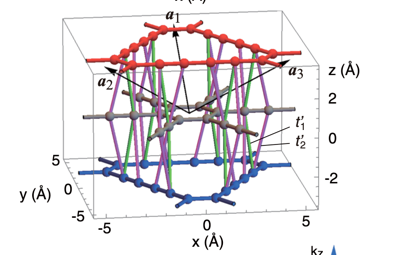

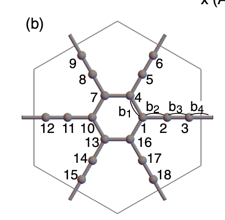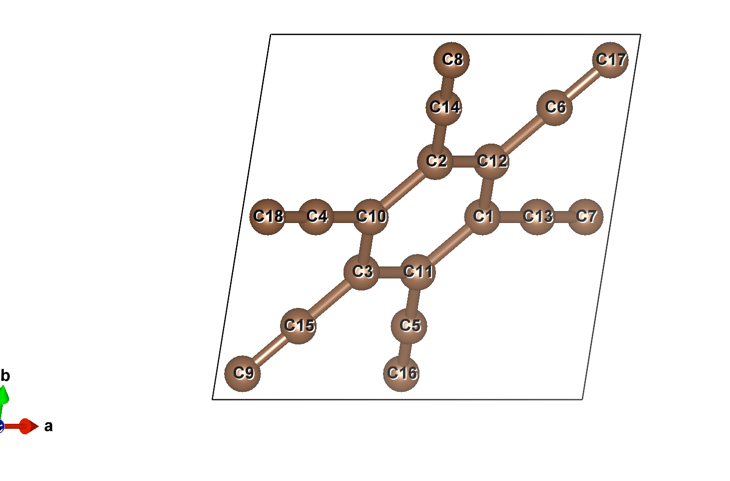

把我们的轨道顺序转成和它一样

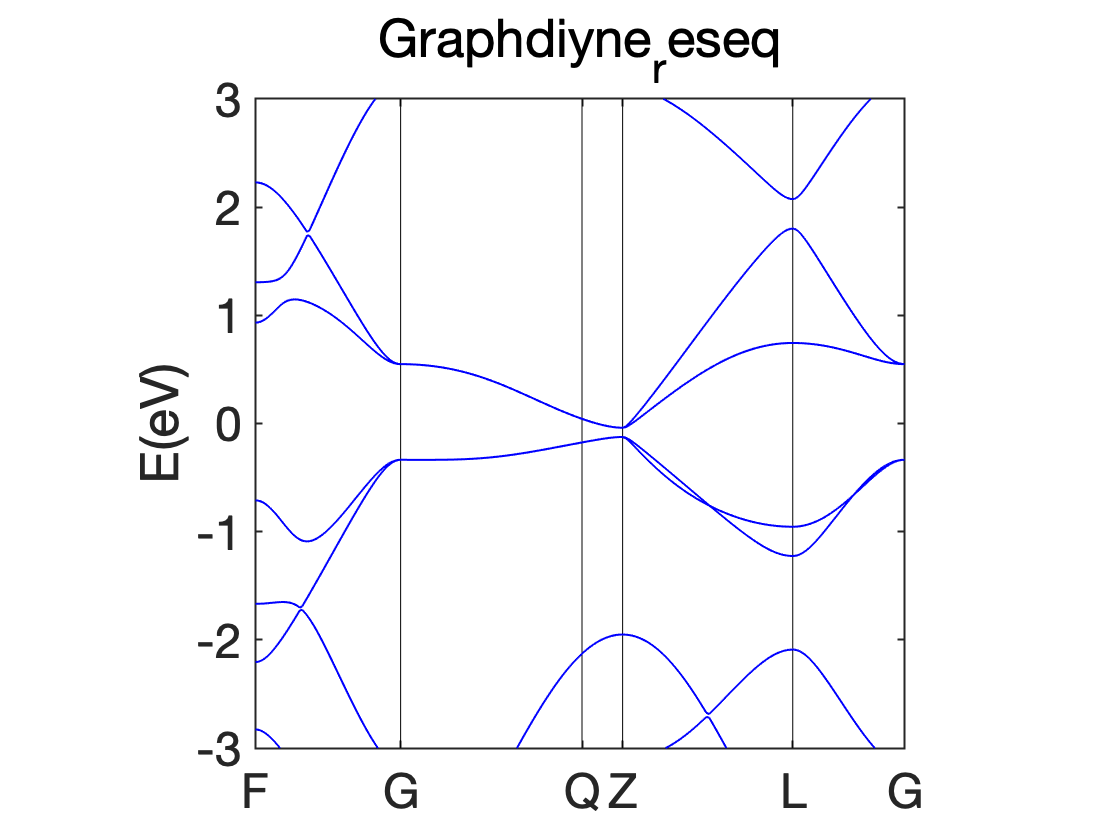

P = [1,13,7,12,6,17,2,14,8,10,4,18,3,15,9,11,5,16];
% P_mat = Pmat_gen(P_list);
GDY3D_reseq = GDY3D_n(P,:);
% bulk band
EIGENCAR =GDY3D_reseq.EIGENCAR_gen();
% plot
[klist_l,kpoints_l,kpoints_name] = GDY3D_reseq.kpath_information();
bandplot(EIGENCAR,[-3,3],'Graphdiyne_reseq','b',klist_l,kpoints_l,kpoints_name);

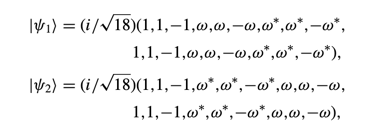

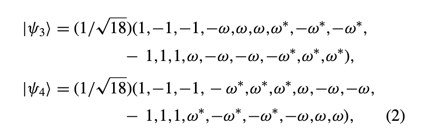

% use 10.1103/PhysRevMaterials.2.054204 basis

w = exp(2*pi*1i/3);
% syms w;
psi(1,:) = (1i/sqrt(18))*[...
    1,1,-1,...
    w,w,-w,...
    w',w',-w',...
    1,1,-1,...
    w,w,-w,...
    w',w',-w'];
psi(2,:) = (1i/sqrt(18))*[...
    1,1,-1,...
    w',w',-w',....
    w,w,-w,...
    1,1,-1,...
    w',w',-w',...
    w,w,-w];
psi(3,:) = (1i/sqrt(18))*[...
    1,-1,-1,...
    -w,w,w,...
    w',-w',-w',...
    - 1,1,1,...
    w,-w,-w,...
    -w',w',w'];
psi(4,:) = (1i/sqrt(18))*[...
    1,-1,-1,...
    - w',w',w',...
    w,-w,-w,...
    - 1,1,1,...
    w',-w',-w',...
    -w,w,w];% BASIS_MAT = [0 0 0 0 0 0 1 0;0 0 0 0 0 0 0 1];%

- 尝试把 HTB 的8个轨道 投影到2 个轨道的子空间

BASIS_MAT = psi;
GDY3D_p = GDY3D_reseq.project(BASIS_MAT);

- 生成能带

EIGENCAR_p = GDY3D_p.EIGENCAR_gen();

- 画出能带

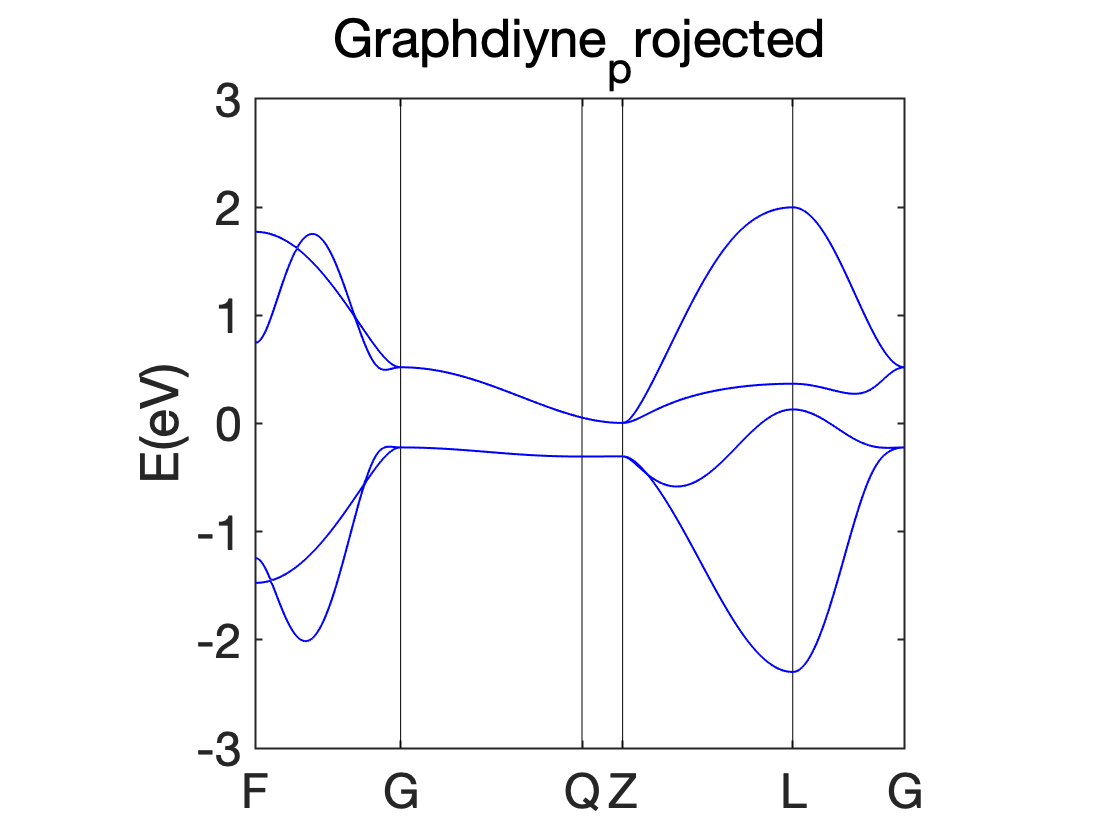

[klist_l,kpoints_l,kpoints_name] = GDY3D_p.kpath_information();
bandplot(EIGENCAR_p,[-3,3],'Graphdiyne_projected','b',klist_l,kpoints_l,kpoints_name);

尝试从WAVECAR定义

OUTCAR =GDY3D_reseq.EIGENCAR_gen(0,-1,[0 0 0.5]);
WAVECAR = OUTCAR.WAVECAR;
BASIS_MAT2 = WAVECAR(:,8:11).';
GDY3D_p2 = GDY3D_reseq.project(BASIS_MAT2);

- 生成能带

EIGENCAR_p2 = GDY3D_p2.EIGENCAR_gen();

- 画出能带

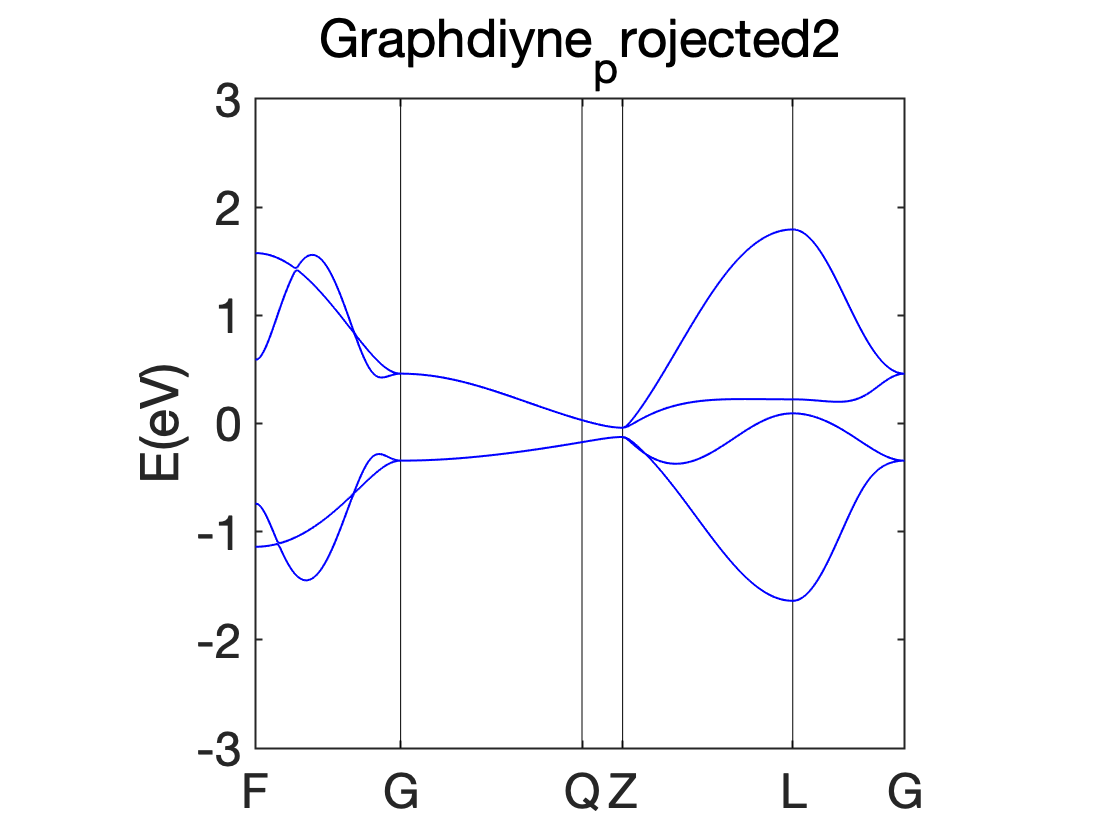

[klist_l,kpoints_l,kpoints_name] = GDY3D_p2.kpath_information();
bandplot(EIGENCAR_p2,[-3,3],'Graphdiyne_projected2','b',klist_l,kpoints_l,kpoints_name);

function P_mat = Pmat_gen(P_list)
P_mat = zeros(length(P_list));
for i = 1:length(P_list)
    P_mat(i,P_list(i))=  1;
end
end